imageFolder='C:\Users\train......'

imageFolder = 'C:\Users\tansu\Desktop\62G.14\5.for train\Train\Median Filter'

imds = imageDatastore(imageFolder, 'LabelSource', 'foldernames', 'IncludeSubfolders',true);
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.9,'randomized');

imageFolderTest='C:\Users\test.................'

imageFolderTest = 'C:\Users\tansu\Desktop\62G.14\5.for train\Test\Median Filter'

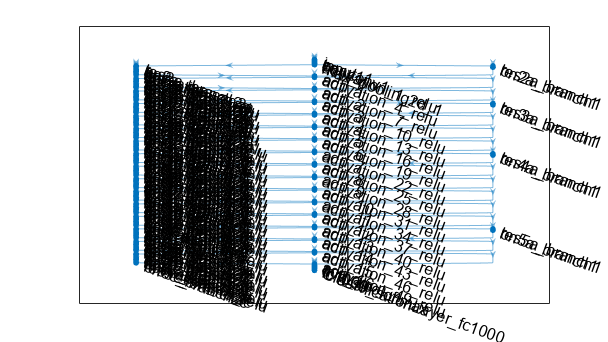

imdsTest = imageDatastore(imageFolderTest, 'LabelSource', 'foldernames', 'IncludeSubfolders',true);

net= resnet50;
lgraph = layerGraph(net);
figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
plot(lgraph)

net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'input_1'
                 InputSize: [224 224 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


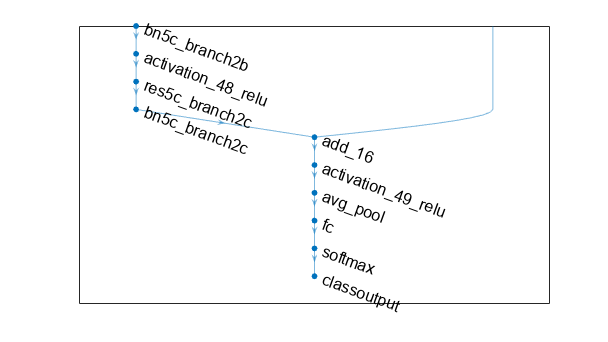

inputSize = net.Layers(1).InputSize;
% lgraph = removeLayers(lgraph, {'loss3-classifier','prob','output'});
lgraph = removeLayers(lgraph, {'fc1000','fc1000_softmax','ClassificationLayer_fc1000'});

numClasses = numel(categories(imdsTrain.Labels));
newLayers = [
    fullyConnectedLayer(numClasses,'Name','fc','WeightLearnRateFactor',10,'BiasLearnRateFactor',10)
    softmaxLayer('Name','softmax')
    classificationLayer('Name','classoutput')];
lgraph = addLayers(lgraph,newLayers);
% lgraph = connectLayers(lgraph,'pool5-drop_7x7_s1','fc');
lgraph = connectLayers(lgraph,'avg_pool','fc');

figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])

layers = lgraph.Layers;
connections = lgraph.Connections;
a=0;
b=0;
c=0;
d=0;
 for i = 1:numel(layers(1:110))  %(layers(1:177))
        if isprop(layers(i),'WeightLearnRateFactor')
            layers(i).WeightLearnRateFactor = 0;
            a=a+1;
            i
            
        end
        if isprop(layers(i),'WeightL2Factor')
            layers(i).WeightL2Factor = 0;
            b=b+1;
        end
        if isprop(layers(i),'BiasLearnRateFactor')
            layers(i).BiasLearnRateFactor = 0;
            c=c+1;
        end
        if isprop(layers(i),'BiasL2Factor')
            layers(i).BiasL2Factor = 0;
            d=d+1;
        end
 end

i = 2

i = 6

i = 9

i = 12

i = 13

i = 18

i = 21

i = 24

i = 28

i = 31

i = 34

i = 38

i = 41

i = 44

i = 45

i = 50

i = 53

i = 56

i = 60

i = 63

i = 66

i = 70

i = 73

i = 76

i = 80

i = 83

i = 86

i = 87

i = 92

i = 95

i = 98

i = 102

i = 105

i = 108

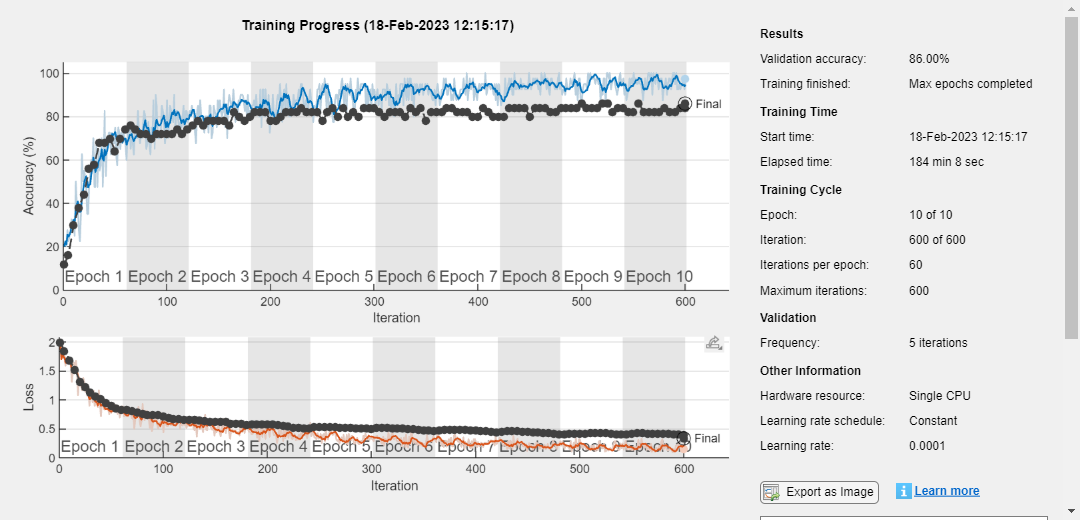

 pixelRange = [-5 5];
imageAugmenter = imageDataAugmenter( ...
    'RandYReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsTest);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',40, ...
    'MaxEpochs',10, ...
    'InitialLearnRate',1e-4, ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',5, ...
    'ValidationPatience',Inf, ...
    'Verbose',false ,...
    'Plots','training-progress');

net = trainNetwork(augimdsTrain,lgraph,options);

[YPred,probs] = classify(net,augimdsValidation);
accuracy = mean(YPred == imdsTest.Labels)

accuracy = 0.8600


name=append('RN_detectedData_i8.mat')

name = 'RN_detectedData_i8.mat'

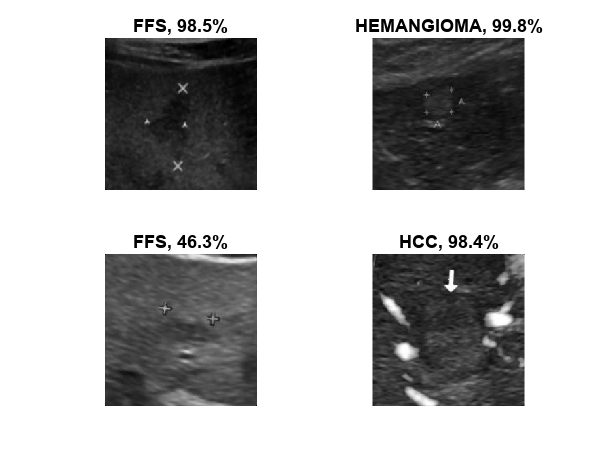

save(name,'net')

idx = randperm(numel(imdsTest.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsTest,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end

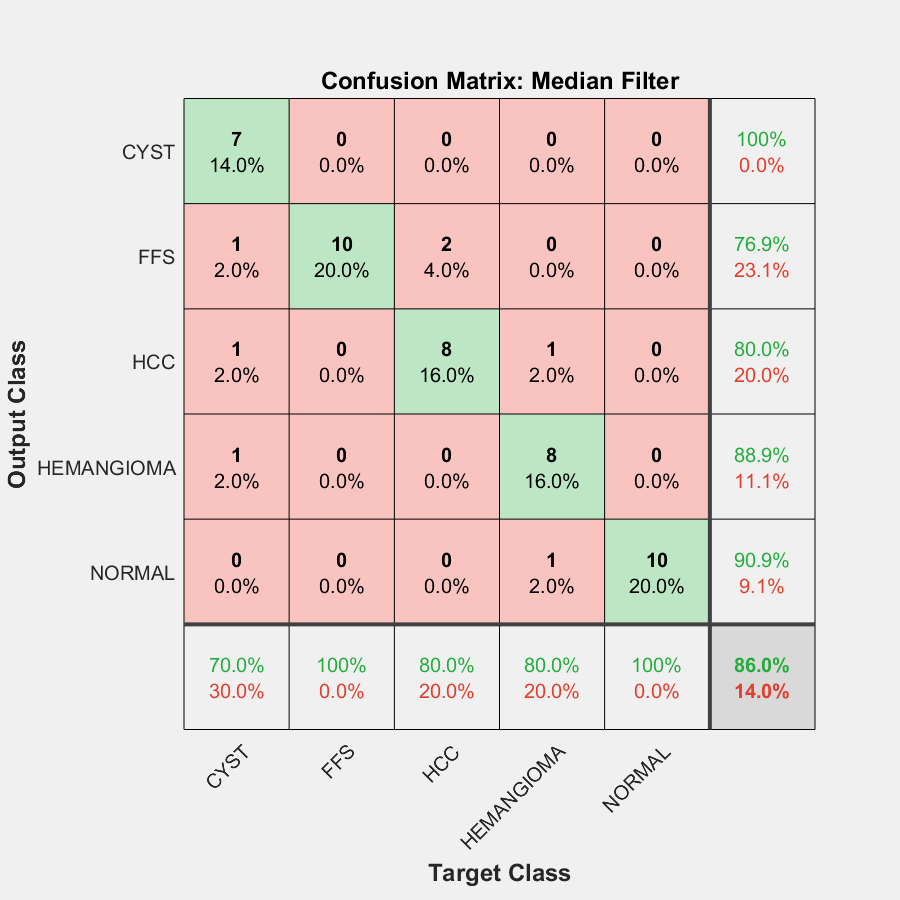

analyzeNetwork(net);
figure;
plotconfusion(imdsTest.Labels,YPred)
title('Confusion Matrix: Median Filter');

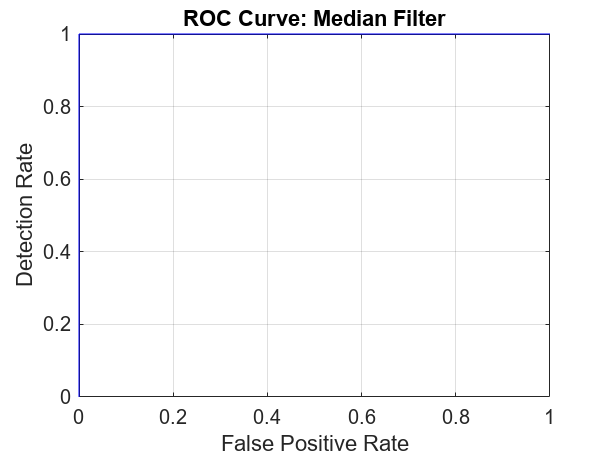


%ROC CURVE
test_labels=double(nominal(imdsTest.Labels));
[fp_rate,tp_rate,T,AUC]=perfcurve(test_labels,probs(:,1),1);
figure;
plot(fp_rate,tp_rate,'-b');
title('ROC Curve: Median Filter');
grid on;
xlabel('False Positive Rate');
ylabel('Detection Rate');

AUC

AUC = single
1